A=sym([1 3 3;2 0 1]'); n=null(A')

$$n = \left(\begin{array}{c} -\frac{1}{2}\\ -\frac{5}{6}\\ 1 \end{array}\right)$$

[num,den]=numden(n);
comden=lcm(den); %lcm: least common multiple
eta=comden*n; disp(eta) %This way i eliminate fractions

$$\left(\begin{array}{c} -3\\ -5\\ 6 \end{array}\right)$$


u=[2 1 1]'; A=[1 3 3;2 0 1]'; n=null(A');
sintheta=dot(u,n)/(norm(u)*norm(n));
degrees=asin(abs(sintheta))*180/pi;
disp(degrees)

   14.1213



degrees = 14.1213

Lab: Angles between two planes

A=[1 3 3; 2 0 1]'; B=[1 0 0 ; 0 1 0]';
n1=null(A');
n2=null(B');
disp([n1 n2])

   -0.3586         0
   -0.5976         0
    0.7171    1.0000



%Apply the formula
c=dot(n1,n2)/(norm(n1)*norm(n2))

c = 0.7171

degrees=acos(abs(c))*180/pi;
disp(degrees);

   44.1814



Lab: angle between subspaces in matlab

A=[1 2;3 0; 3 1];
B=[1 0; 0 1; 0 0];
disp(A)

     1     2
     3     0
     3     1



disp(B)

     1     0
     0     1
     0     0



nA=null(A')

nA =    -0.3586
   -0.5976
    0.7171


nB=null(B')

nB =      0
     0
     1


c=dot(nA,nB)/(norm(nA)*norm(nB))

c = 0.7171

degrees=acos(abs(c))*180/pi

degrees = 44.1814

Lab: component of a vector along another vector

u=[-2 1]'; v=[5 -2];

res =     4.8000
   -2.4000


vu=dot(u,v)/norm(u)^2*u;

Lab: tangent line to a regular curve in $\mathbb R^2$

clf;
syms q t real; rho=1.5; % We choose  a costanst rho
x1=rho*cos(t); x2=rho*sin(t);
x=[x1;x2] % Curve

$$x = \left(\begin{array}{c} \frac{3\,\cos\left(t\right)}{2}\\ \frac{3\,\sin\left(t\right)}{2} \end{array}\right)$$

ezplot(x1,x2); hold on
xp=diff(x) %Derivative of the curve

$$xp = \left(\begin{array}{c} -\frac{3\,\sin\left(t\right)}{2}\\ \frac{3\,\cos\left(t\right)}{2} \end{array}\right)$$

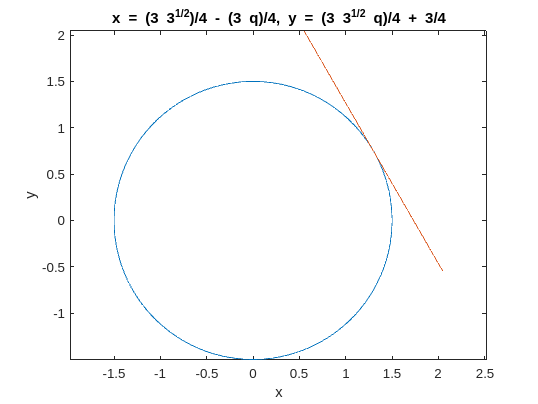

t0=pi/6; %Define a costant t0, theta
P0=subs(x,'t',t0);
xpP0=subs(xp,'t',t0);
T=P0+q*xpP0; %tangent line at P0
ezplot(T(1),T(2),[-1 1]); 

Lab: normal line to a regular curve in $\mathbb R^2$

clf;
syms q t real; rho=1.5; x1=rho*cos(t); x2=rho*sin(t); x=[x1;x2] % Curve

$$x = \left(\begin{array}{c} \frac{3\,\cos\left(t\right)}{2}\\ \frac{3\,\sin\left(t\right)}{2} \end{array}\right)$$

ezplot(x1,x2); hold on
xp=diff(x) %Derivative of the curve

$$xp = \left(\begin{array}{c} -\frac{3\,\sin\left(t\right)}{2}\\ \frac{3\,\cos\left(t\right)}{2} \end{array}\right)$$

t0=pi/6; %Define a costant t0, theta
P0=subs(x,'t',t0);
xpP0=subs(xp,'t',t0);
T=P0+q*xpP0; %tangent line at P0
ezplot(T(1),T(2),[-1 1]); 

syms q t real; rho=1.5;
x1=rho*cos(t); x2=rho*sin(t);
x=[x1;x2] % Curve

$$x = \left(\begin{array}{c} \frac{3\,\cos\left(t\right)}{2}\\ \frac{3\,\sin\left(t\right)}{2} \end{array}\right)$$

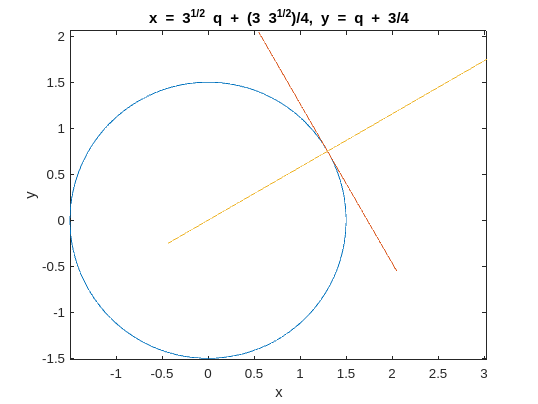

xp=diff(x);
t0=pi/6;
P0=subs(x,'t',t0);
xpP0=subs(xp,'t',t0);
N0=null(xpP0.');
N=P0+q*N0;
ezplot(N(1),N(2),[-1 1]);

Solve the previous problem numerically

clf;
t=linspace(0,2*pi,101); rho=1.5; %Define curve with samples
x1=rho*cos(t); x2=rho*sin(t);
P=[x1;x2]; %sample points;
disp(P)

    1.5000    1.4970    1.4882    1.4734    1.4529    1.4266    1.3947    1.3572    1.3145    1.2665    1.2135    1.1558    1.0935    1.0268    0.9561    0.8817    0.8037    0.7226    0.6387    0.5522    0.4635    0.3730    0.2811    0.1880    0.0942    0.0000   -0.0942   -0.1880   -0.2811   -0.3730   -0.4635   -0.5522   -0.6387   -0.7226   -0.8037   -0.8817   -0.9561   -1.0268   -1.0935   -1.1558   -1.2135   -1.2665   -1.3145   -1.3572   -1.3947   -1.4266   -1.4529   -1.4734   -1.4882   -1.4970   -1.5000   -1.4970   -1.4882   -1.4734   -1.4529   -1.4266   -1.3947   -1.3572   -1.3145   -1.2665   -1.2135   -1.1558   -1.0935   -1.0268   -0.9561   -0.8817   -0.8037   -0.7226   -0.6387   -0.5522   -0.4635   -0.3730   -0.2811   -0.1880   -0.0942   -0.0000    0.0942    0.1880    0.2811    0.3730    0.4635    0.5522    0.6387    0.7226    0.8037    0.8817    0.9561    1.0268    1.0935    1.1558    1.2135    1.2665    1.3145    1.3572    1.3947    1.4266    1.4529    1.4734    1.4882    1.4970

j=10;
t0=t(j);
P0=P(:,j);
disp(P0)

    1.2665
    0.8037



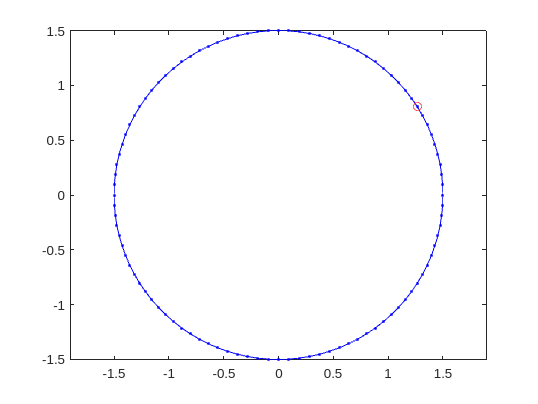

plot(P(1,:),P(2,:),'.b-',P0(1),P0(2),'or'); axis equal; hold on;

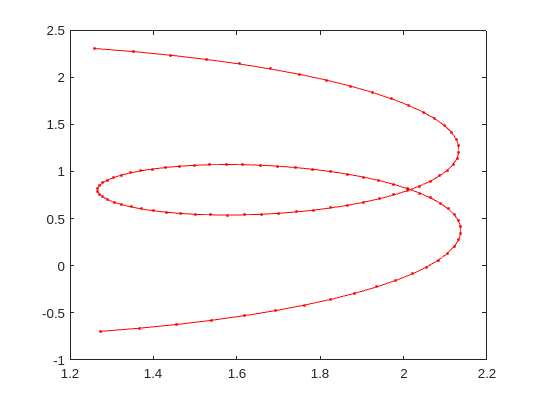



h=.01;
t=linspace(0,2*pi,100);
X1p=(rho*cos(t+h) - rho*cos(t))/h; %Approximate derivative
X2p=(rho*sin(t+h) - rho*sin(t))/h;
%Interesting experiment:
clf;
Tg(1,:)=P0(1)+q.*X1p;
Tg(2,:)=P0(2)+q.*X2p;
%This curve describes all infinite the tangent line to points for the circle
plot(Tg(1,:),Tg(2,:),'.r-'); 

clf;

X1p0=X1p(:,j)

X1p0 = -0.8173

X2p0=X2p(:,j)

X2p0 = 1.2578



q=linspace(-1,1,100);
T(1,:)=P0(1)+q.*X1p0;
T(2,:)=P0(2)+q.*X2p0;
disp(T(1,:))

disp(T(2,:))


tangent_matrix=[X1p0; X2p0]';
nj=null(tangent_matrix)

nj =     0.8385
    0.5448


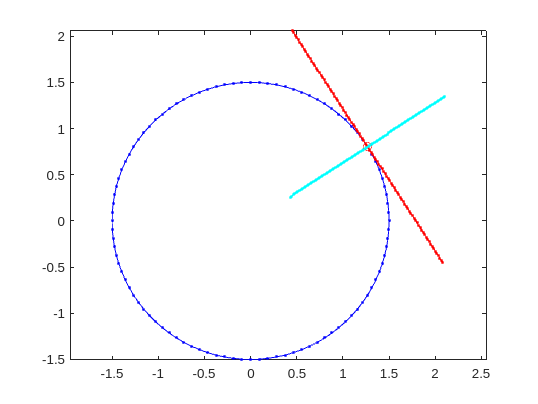

N(1,:)=P0(1)+q.*nj(1);
N(2,:)=P0(2)+q.*nj(2);

plot(P(1,:),P(2,:),'.b-',P0(1),P0(2),'or'); axis equal; hold on;
plot(T(1,:),T(2,:),'.r-');
plot(N(1,:),N(2,:),'.c-');

Display the tangent plane to a surface

clf;
syms x y real; f=x^2+y^2;
X=-3; Y=-2; Z=subs(f,{'x','y'},{X,Y});
P=[x;y;f];
J=jacobian(P);
disp(J)

$$\left(\begin{array}{cc} 1 & 0\\ 0 & 1\\ 2\,x & 2\,y \end{array}\right)$$

J0=subs(J,{x,y},{X,Y}); v=double(J0);
disp(J0);

$$\left(\begin{array}{cc} 1 & 0\\ 0 & 1\\ -6 & -4 \end{array}\right)$$

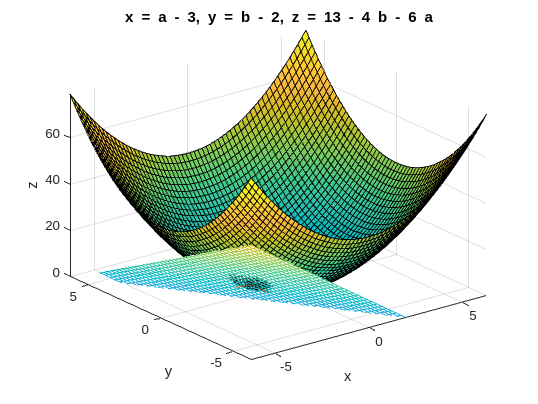


P0=[X Y Z]';
ezsurf(f); hold on;
plot3(P0(1),P0(2),P0(3));
syms a b real; P=P0+J0*[a;b]; % tangent plane;
ezmesh(P(1),P(2),P(3));
quiver3([X X], [Y Y], [Z Z], v(1,:), v(2,:), v(3,:),1);


J=[sym(eye(2));jacobian(f)] %Jacobian as approximation

$$J = \left(\begin{array}{cc} 1 & 0\\ 0 & 1\\ 2\,x & 2\,y \end{array}\right)$$

J0=subs(J,{x,y},{X,Y}); v=double(J0); disp(v);

     1     0
     0     1
    -6    -4



J=[sym(eye(2)); gradient(f).']; %Computed with gradient as approximation
J0=subs(J,{x,y},{X,Y}); v=double(J0);disp(v);

     1     0
     0     1
    -6    -4



Now solve the same problem numerically

clf; clear J0 P0 P w x y a b x0 y0 f0 f X Y xX yY
w=0.1; [x,y]=meshgrid(-6:w:6);
f=x.^2+y.^2;
X=-3; Y=-2;
xX=min(x-X)

xX =    -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000


yY=min(y-Y)

yY =     -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4


[h,k]=find(x==min(xX) & y==min(yY))

h = 21

k = 31

x0=x(33,19)

x0 = -4.2000

y0=y(33,19)

y0 = -2.8000

f0=x0.^2+y0.^2

f0 = 25.4800

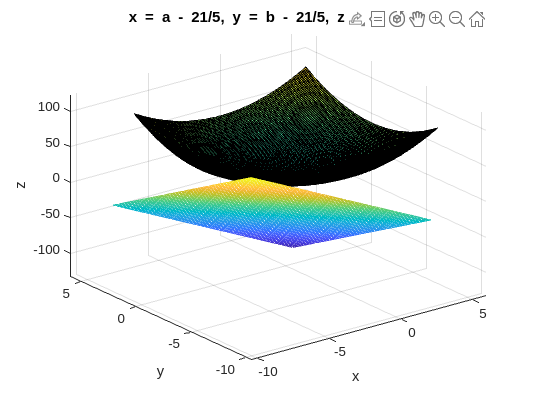

P0=[x0,y0,f0];

surf(x,y,f);  axis tight; hold on;
[fx,fy]=gradient(f,w);
J=[eye(2);fx(j,j),fy(j,j)];
%P=P0+J*[a;b]
syms a b real; P=P0+J*[a;b];
ezmesh(P(1),P(2),P(3))
quiver3([P0(1) P0(1)], [P0(2) P0(2)],[P0(3) P0(3)],J(1,:),J(2,:),J(3,:),'r');


%tangent_plane=@(x,y) f0+fx(j)*(x-x0)+fy(j)*(y-y0);
%surf(x,y,tangent_plane(x,y));
